# **Pràctica 2: Anàlisi de la resposta freqüencial d’un sistema de control digital**

Les pràctiques de l’assignatura Control amb Computador consisteixen en l’estudi d’un servomecanisme de posicionament angular controlat per un PC. Les sessions de laboratori P1 i P2 es centren, respectivament, en l’anàlisi experimental de les respostes temporal i freqüencial del sistema. Les sessions P3 i P4 es dediquen al disseny de controladors PID. Finalment, en la pràctica P5 es dissenyaran controladors en camp freqüencial.

**OBJECTIU: Anàlisi de la resposta freqüencial del sistema de control digital de velocitat. Anàlisi de l'estabilitat mitjançant el criteri de Nyquist**

**En aquesta sessió l'estudiant ha de:**

- **Trobar experimentalment la resposta freqüencial del sistema en llaç obert.**

- **Aplicar el criteri de Nyquist per determinar el rang de valors d'un controlador proporcional pels que el sistema en llaç tancat és estable, i verificar-ho experimentalment.**

- **Comparar els resultats obtinguts amb els resultats teòrics.**

% Canvi entre les dades de l'experiment i els del directori Resultats
% Si voleu utilitzar les dades del directori Resultats = false
% Si voleu utilitzar dades pròpies = true
useExperimentalData = false;

# Exercici 7: Obtenció del diagrama de Nyquist

Usant els valors del model a la pràctica 1 representar en un mateix diagrama la resposta freqüencial de:

- El sistema en llaç obert de velocitat de temps continu.

- El sistema en llaç obert de temps discret amb el període de mostratge de $T_s =0\ldotp 01s$.

- Identifiqueu sobre les gràfiques les zones corresponents a altes i baixes freqüències.

- Justifiqueu les diferències que s'observen entre les gràfiques en cadascuna de les bandes de freqüències.

% Paràmetres de la planta
K_mot=0.82; %[rpm/V]
T_mot=0.24; %seg

% Període de mostratge
Ts=0.01;

% Funció de transferència continu i digital del model
F=tf([K_mot],[T_mot 1])


F =
 
     0.82
  ----------
  0.24 s + 1
 
Continuous-time transfer function.



Fd=c2d(F,Ts)


Fd =
 
   0.03346
  ----------
  z - 0.9592
 
Sample time: 0.01 seconds
Discrete-time transfer function.



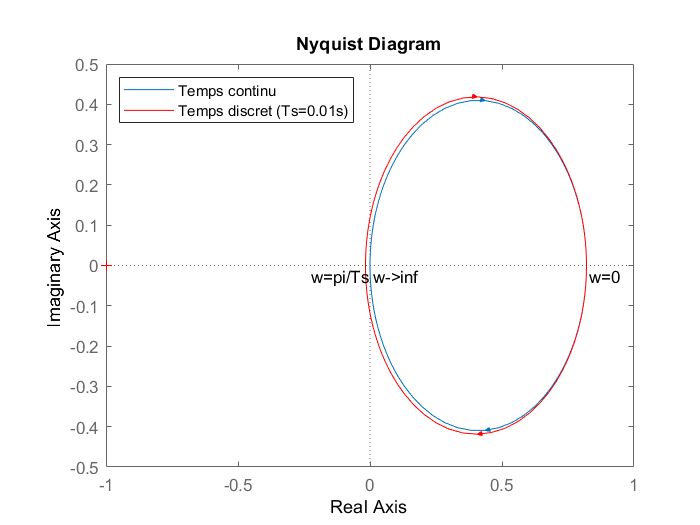


% Diagrames de Nyquist
figure
nyquist(F)
hold on 
nyquist(Fd,'red')
legend('Temps continu',strcat('Temps discret ',strcat(strcat(' (Ts=',num2str(Ts)),'s)')),'location','NorthWest');
text(dcgain(F)+0.010,-0.025,'w=0');
text(real(freqresp(Fd,pi/Ts))-0.205,imag(freqresp(Fd,pi/Ts))-0.025,'w=pi/Ts');
text(freqresp(F,inf)+0.010,freqresp(F,inf)-0.025,'w->inf');  

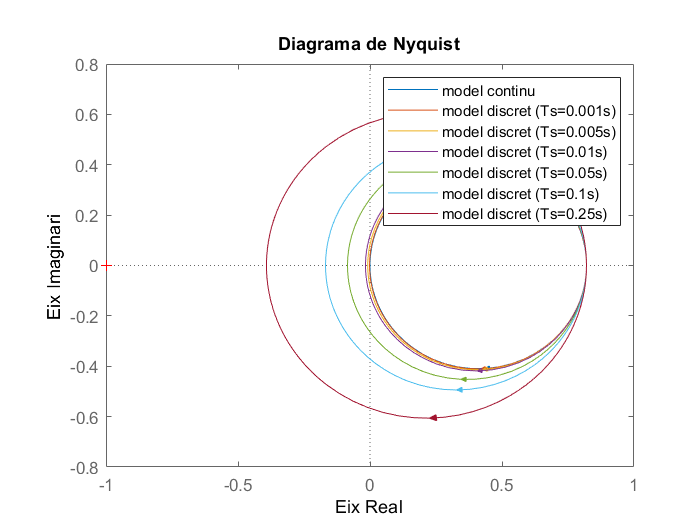


% visualitzem el Nyquist per a diferents períodes de mostratge
    i=1;
    Ts=[0.001 0.005 0.01 0.05 0.1 0.25];
    [fils cols]=size(Ts);
    legenda={'model continu'};
    while (i<=cols)
        legenda={char(legenda);strcat(strcat('model discret (Ts=',num2str(Ts(1,i))),'s)')};
        i=i+1;
    end
    legenda=char(legenda);
    figure;
    nyquist(F);
    hold on;
    %legend('model continu');
    i=1;        
    while (i<=cols)
        nyquist(c2d(F,Ts(1,i),'zoh'));
        % legend(strcat(strcat('model discret(Ts=',num2str(Ts(1,i))),'s)'));
        i=i+1;
    end
    legend(legenda);
    title('Diagrama de Nyquist');
    xlabel('Eix Real');
    ylabel('Eix Imaginari');

Com es pot observar, a més Ts, més s'apropa el diagrama al punt crític (-1,0) amb el que el sistema es fa cada vegada més inestable.

# Exercici 8: Obtenció experimental del diagrama de Nyquist del sistema discret

Obrir i executar el model P2_Ex8.slx. Generar un senyal sinusoïdal d'entrada d'amplitud 2V i freqüència 0,25Hz. Mesurar el guany i desfasament del senyal de sortida. Repetir el procés per a les freqüències de 0.5, 0.8, 1, 2, 4, 5, 10, 20 i 50Hz. Utilitza un període de mostreig de 0,01 segons.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



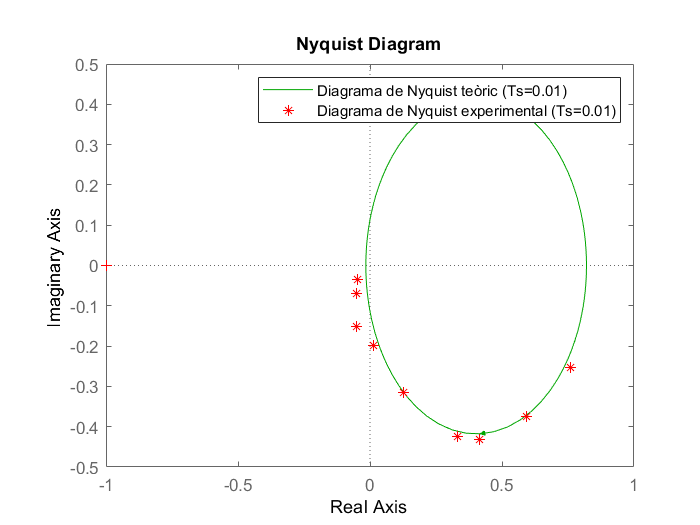

if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex8.slx
    run P2_Ex8.slx;
else
    % Vector de guanys experimentals
    G=[0.8 0.7 0.6 0.54 0.34 0.2 0.16 0.085 0.06];
    % Vector de desfasaments experimentals (en radiants)
    F=[18.45 32.4 46.08 52 68.4 86.4 108 126 144]*(-pi/180);
    % Càlcul del complex en forma cartesiana
    X=real (G.*exp(F*j));
    Y=imag(G.*exp(F*j));
    
    % Introducció dels paràmetres de la planta
    K0=0.82;
    tau0=0.26;
    planta=tf([K0],[tau0,1])
    
    % Models de temps discret
    Ts=0.01;
    plantad=c2d(planta,Ts,'zoh');
    
    % Dibuixem el diagrama de Nyquist teòric i experimental
    figure
    nyquist(plantad,'g')
    hold on
    plot(X,Y, 'r*' )
    legend('Diagrama de Nyquist teòric (Ts=0.01)','Diagrama de Nyquist experimental (Ts=0.01)')
end

Com podem veure, el diagrama de Nyquist experimental s'assembla a la teòrica. Les petites diferències vénen dels errors de càlculs, ja que a major freqüència menor és la quantitat de mostres i més difícil es fa de mesurar els canvis produïts.

# Exercici 9: Aplicació del criteri de Nyquist

Usant el diagrama teòric apliqueu el criteri de Nyquist per a:

- Analitzar l'estabilitat del sistema de temps discret.

- Trobar el rang de valors del controlador proporcional $K_P$ que fan que el sistema de temps discret en llaç tancat amb realimentació de velocitat sigui estable.

Compareu-ho amb el cas de temps continu comprovant com varien els diagrames teòrics a l'augmentar $K_P$. Verifiqueu experimentalment el resultat analitzant la resposta al graó per $K_P$=5 i per un valor de $K_P$ fora dek rang trobat, tant en simulació com experimentalment.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



Ts = 0.0100


sistema_discreto =
 
   0.03094
  ----------
  z - 0.9623
 
Sample time: 0.01 seconds
Discrete-time transfer function.



gain = -0.0158

Kp_limit = 63.4225

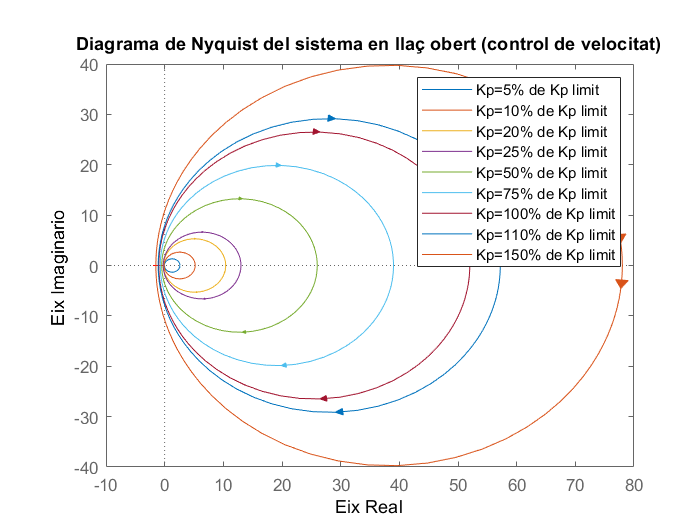

if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex9b.slx;
    run P2_Ex9b.slx;
else
    % Model del sistema (des del fitxer de la pràctica 1: exercici 4)
    K0=0.82;
    tau0=0.26;
    planta=tf(K0,[tau0 1])
        
    % Període de mostratge
    Ts=0.01
    Kp=sym('K');
    
    % Determinació del sistema digital
    sistema_discreto=c2d(planta,Ts,'zoh')
    
    % Determinació de la Kp_limit
    gain=real(freqresp(sistema_discreto,pi/Ts))
    Kp_limit=-1/gain
    
    
    % Percentatges de Kp_limit
    vector=[5 10 20 25 50 75 100 110 150];
    vector=[vector; vector*Kp_limit/100];
    [fils cols]=size(vector);
    i=1;
    figure;
    hold on;
    
    while (i<=cols)
        if (vector(1,i)<100)
            nyquist(sistema_discreto*vector(2,i));
        elseif (vector(1,i)==100)
            nyquist(sistema_discreto*vector(2,i));
        else
            nyquist(sistema_discreto*vector(2,i));
        end
        if (i==1)
            legenda={strcat(strcat('Kp=',num2str(vector(1,i))),'% de Kp limit')};
        else
            legenda={char(legenda);strcat(strcat('Kp=',num2str(vector(1,i))),'% de Kp limit')};        
        end
        i=i+1;
    end
    legenda=char(legenda);
    legend(legenda);
    title('Diagrama de Nyquist del sistema en llaç obert (control de velocitat)');
    xlabel('Eix Real');
    ylabel('Eix Imaginario');
end

Com es pot observar, a més Kp, més gran és el diagrama de Nyquist, amb la qual cosa, més inestable es torna el sistema. 

# Exercici 10: Obtenció del diagrama de Bode teòric

Usant el model del sistema i la transformació bilineal $\mathrm{d2c}\left(\ldotp \ldotp \ldotp ,\mathrm{'Tustin'}\right)$, representeu el diagrama de Bode i determinar a partir d'aquest diagrama el marge de guany i el marge de fase. Relacioneu el marge de guany amb el $K_P$ crític de l'apartat anterior.

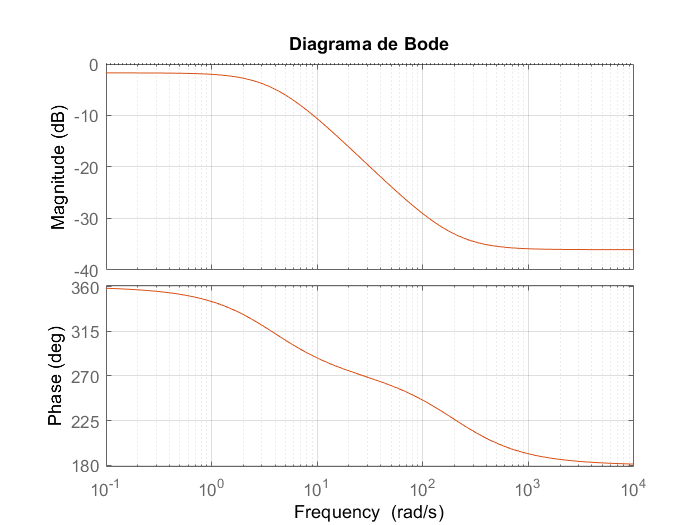

clc;
close all;
clear all;
% Model de sistema (obrim el fitxer creat a la pràctica 1: exercici 4)
   K0=0.82;
    tau0=0.26;
    Kt=0.017;
    planta=tf([K0],[tau0 1]);
    
% Període de mostratge
Ts=0.01;

% Sistema teòric
sistema_discreto=c2d(planta,Ts,'zoh');
sistema_bilineal=d2c(sistema_discreto,'tustin');

% Imatge dels marges de fase / guany de Bode
figure(1);
bode(sistema_bilineal);
hold on;
grid on;
[Gm,Pm,Wcg,Wcp]=margin(sistema_bilineal);
margin(sistema_bilineal);
title('Diagrama de Bode');

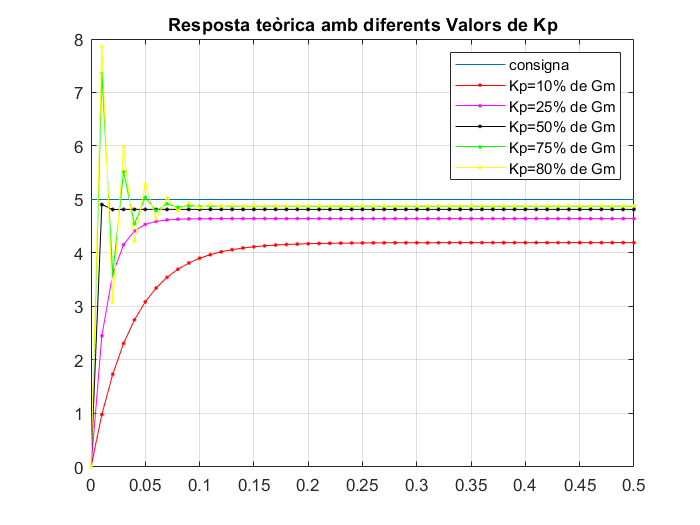


Vmax=5;
% Definim un temps
Tx=0.0:Ts:50*Ts;
% definim uns consigna (graó d'alçada Vmax)
X =[Vmax*ones(size(Tx))];
% definim un conjunt de Kp's per les que volem simular el sistema
% expressades com a percentatge de Gm (ó Kp_max)
Kp=[10 25 50 75 80]';
Kp=[Kp (1/100)*Kp*Gm];
% simulem el comportament del sistema per a diferents kp's
[fils cols]=size(Kp);
i=1;
% el vector Y emmagatzema les respostes del sistema davant la consigna
% amb diferents constants de proporcionalitat
Y=[];
while (i<=fils)
    % la funció model_discret(...) conté una modelització del sistema en llaç
    % tancat i controlador proporcional
    Y=[Y; Kt*model_discret(0,K0/Kt,Kp(i,2),Kt,tau0,Ts,X)];
    i=i+1;
end

figure(2);
T_MAX=max(Tx);
T_MIN=min(Tx);
Y_MAX=max(max(Y));
Y_MIN=min(min(Y));

% dibuxem la consigna
plot(Tx,X);
hold on;
grid on;
% dibuxem les simulacions del sistema
i=1;
styles=['r.-';'m.-';'k.-';'g.-';'y.-';'c.-'];
[sty_fil sty_col]=size(styles);
llegenda={'consigna'};
while (i<=fils)
    plot(Tx,Y(i,:),styles(mod(i,sty_fil),:));
    llegenda={char(llegenda);strcat(strcat('Kp=',num2str(Kp(i,1))),'% de Gm')};
    i=i+1;
end
title('Resposta teòrica amb diferents Valors de Kp');
llegenda=char(llegenda);
legend(llegenda);

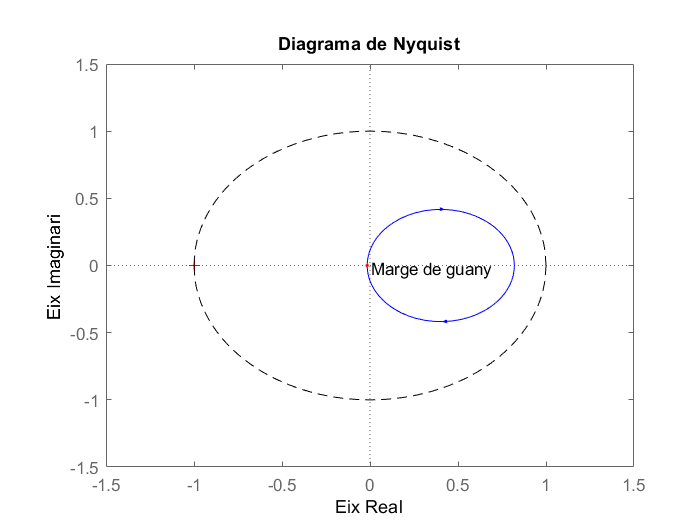


% nyquist del sistema discret
figure(3);
hold on;
nyquist(sistema_discreto,'b-');
freq_resp=freqresp(sistema_discreto,Wcp);
point=[real(freq_resp) imag(freq_resp)];
% dibuixem el punt corresponent al marge de fase i marge de guany
text(point(1,1)+0.02,point(1,2)-0.02,'Marge de fase');
plot(point(1,1),point(1,2),'r.');
freq_resp=freqresp(sistema_discreto,pi/Ts);
point=[real(freq_resp) imag(freq_resp)];
text(point(1,1)+0.02,point(1,2)-0.02,'Marge de guany');
plot(point(1,1),point(1,2),'r.');
axis([-1.5 1.5 -1.5 1.5]);
title('Diagrama de Nyquist');
xlabel('Eix Real');
ylabel('Eix Imaginari');
x=[0 point(1,1)]';
y=[0 point(1,2)]';
circumf;